cd /home/mic-ciciolla/Documents/università/underactuated-robs/UnderActuatedRobotics/
clc
pause(0.1)
clear
pause(0.1)

# One-Legged Hopping Robot

#### Parameters


M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; %Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^3; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^4; % [Nt/m]
BG=75; % [Nt-s/m]

H=0.4; %[m]

g=9.8;

#### Initial Conditions

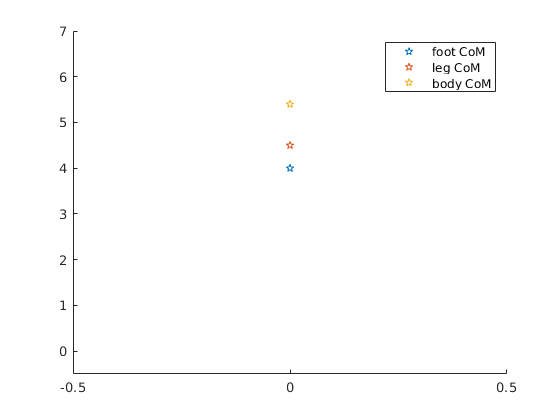

% theta
ini_theta1=0;
ini_theta1_d=0;

ini_theta2=0;
ini_theta2_d=0;

% w
ini_w=k0;
ini_w_d=0;

% y
ini_y0=4;
ini_y0_d=0;

ini_y1=ini_y0+r1;
ini_y1_d=0;

ini_y2=ini_y1+r2+ini_w-r1;
ini_y2_d=0;

% x
ini_x0=0;
ini_x0_d=0;

ini_x1=0;
ini_x1_d=0;

ini_x2=0;
ini_x2_d=0;

figure()
hold on;
plot(ini_x0,ini_y0,'o','Marker',"pentagram");
plot(ini_x1,ini_y1,'o','Marker',"pentagram");
plot(ini_x2,ini_y2,'o','Marker',"pentagram");
legend("foot CoM","leg CoM","body CoM")
ylim([-0.5,7]); xlim([-0.5,0.5]);

#### Theta1_desired for torque control (equation 1)

theta1_des=pi/4;

SIMULINK

simtime=10; %simulation time
SimDec=sim('HoppingRobotModel3',simtime); %Execution of the simulation in Simulink

Invalid setting in 'HoppingRobotModel3/desired_energy' for parameter 'After'.

Caused by:
    Error using HoppingRobot2 (line 68)
    Error evaluating parameter 'After' in 'HoppingRobotModel3/desired_energy'
        Error using 